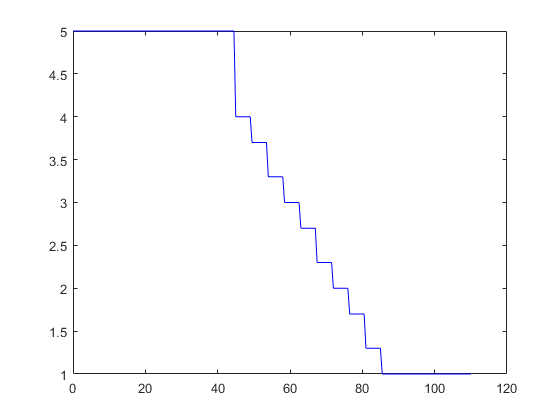

p= 0:0.5:110;
p_max=90;  

note1 = @(p,p_max) ...
        interp1([0   50  55  60  65  70  75  80  85  90  95 1e10]/100, ...
                [5   4   3.7 3.3 3   2.7 2.3 2   1.7 1.3 1  1], ...
                p/p_max, ...
                'previous');
plot(p,note1(p,p_max),'b')

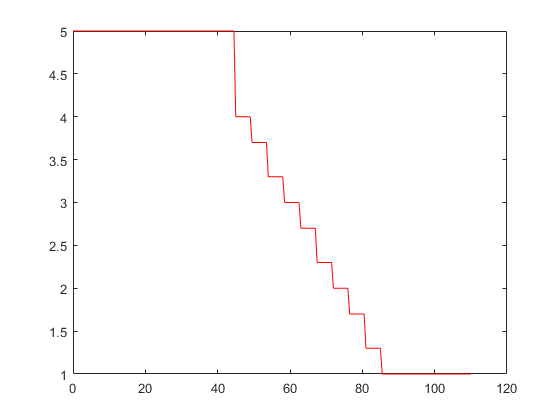



note2 = @(p,p_max) ...
        round(ceil(interp1([0.5 0.95],[12 3],min(0.95,p/p_max),'linear',15))/3,1);
plot(p,note2(p,p_max),'r') 

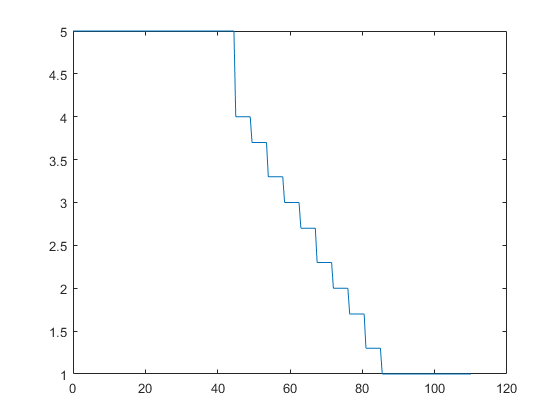


 
note3= @(p,p_max) ...
      (p/p_max >= 0.5) .* max(round(10*ceil(-20*p/p_max + 22)/3)/10, 1.0) + ...
      (p/p_max <  0.5) .* 5.0;
plot(p,note3(p,p_max))